r_W =    1.000000000000000
   0.947760022019941
   0.888610559414604
   0.821637732285235
   0.745806815933439
   0.659945920667682
   0.562730241762116
   0.452658029460422
   0.327828298474595
   0.189715450506132


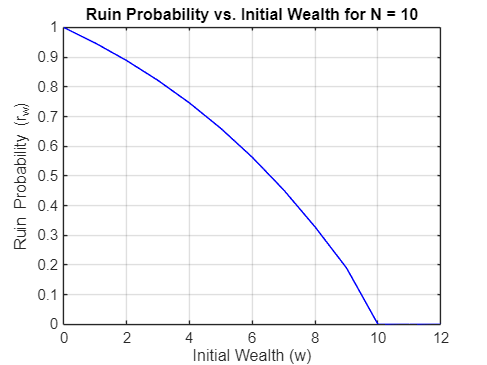

r_W =    1.000000000000000
   0.999739155242819
   0.999443810033769
   0.999109401194383
   0.998730762000541
   0.998302042354923
   0.997816618401121
   0.997266990182932
   0.996644665767615
   0.995940030042804


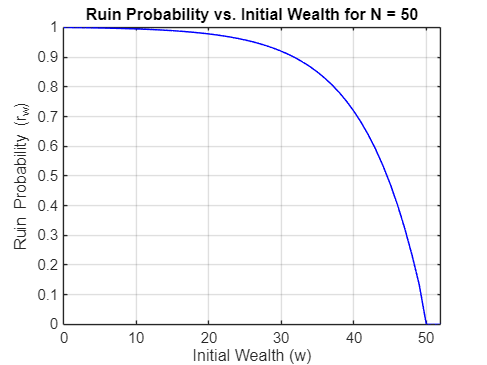

r_W =    1.000000000000000
   0.999999477438672
   0.999998885761131
   0.999998215825768
   0.999997457281866
   0.999996598409679
   0.999995625939354
   0.999994524845913
   0.999993278117106
   0.999991866490574


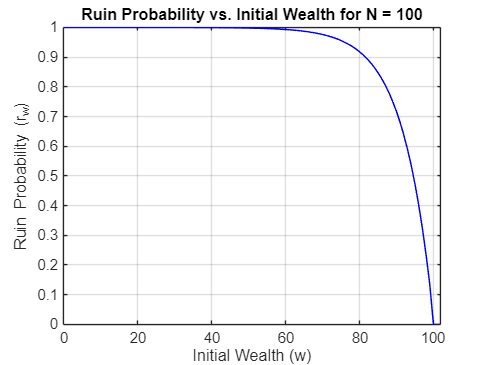

format long

N_values = [10, 50, 100]; 
n = length(N_values);
p_1 = 25/72;
p_2 = 5/72;
p_3 = 1/216;
q = 125/216;

%S_0 = zeros(1, N+2);
%S_0(w+1) = 1; % Set w-th column

%disp(S_0);

for i = 1:n
    N = N_values(i);

P = zeros(N+3, N+3);  

P(1,1) = 1;
P(N+1,N+1) = 1;
P(N+2,N+2) = 1; 
P(N+3,N+3) = 1; 

for row = 2:N
    P(row, row-1) = q; 
    P(row, row) = 0;
    P(row, row+1) = p_1;
    P(row, row+2) = p_2;
    P(row, row+3) = p_3;
end

P;
Q = P(2:N, 2:N); %transient to transient 
R = [P(2:N, 1), P(2:N, N+1), P(2:N, N+2), P(2:N, N+3)]; %transient to absorption
I = eye(size(Q));
F = inv(I-Q);
H = F*R;
H_full = [P(1,1), P(1,N+1), P(1,N+2), P(1,N+3); H; P(N+1,1), P(N+1,N+1), P(N+1,N+2), P(N+1,N+3); P(N+2,1), P(N+2,N+1), P(N+2,N+2), P(N+2,N+3); P(N+3,1), P(N+3,N+1), P(N+3,N+2), P(N+3,N+3)];
r_W = H_full(:,1)
figure;
plot(0:N+2, r_W, 'b', 'LineWidth', 1);
xlabel('Initial Wealth (w)');
ylabel('Ruin Probability (r_w)');
title(['Ruin Probability vs. Initial Wealth for N = ', num2str(N)]);
grid on;
xlim([0 N+2])
ylim([0.000 1.000])

end